# Initialise

clc; clear all; close all;

currentFolder='C:\Users\elzaatas\OneDrive - Coventry University\cobot-intuitive-teach\GenLfD-tutorial\';
cd(currentFolder);
addpath(genpath(currentFolder));

task='obstacleavoid';
bool_Simulation=0;
if bool_Simulation==1
    task_path = strcat('Simulation\data\',task);
else
    task_path = strcat('tasks\',task);
end
boolLive=false;

# Retrieve Images in Real time

The images are static task setting. They can be shot in realtime from simulation.

vrep=remApi('remoteApi');
vrep.simxFinish(-1);
id=vrep.simxStart('127.0.0.1',19997,true,true,1000,5); % connect simulation to matlab
if id < 0
    system(strcat(task_path,"\RobotScene.ttt")); % open simulation software if not already open
end
for nbtry=1:100
    vrep=remApi('remoteApi');
    vrep.simxFinish(-1);
    id=vrep.simxStart('127.0.0.1',19997,true,true,5000,5); % connect simulation to matlab
    if id >= 0
        returnCode=vrep.simxStartSimulation(id,vrep.simx_opmode_oneshot); % start simulation
        break;
    end
end
returnCode=vrep.simxStartSimulation(id,vrep.simx_opmode_oneshot); % start simulation

% get object handles from simulation
[camerro,vision1] = vrep.simxGetObjectHandle(id,'Vision_sensor0',...
    vrep.simx_opmode_oneshot_wait); % the camera to read images from
[camerro,target] = vrep.simxGetObjectHandle(id,'Target',...
    vrep.simx_opmode_oneshot_wait);% the cobot's end effector
[camerro,UR3_base] = vrep.simxGetObjectHandle(id,'UR3',...
    vrep.simx_opmode_oneshot_wait);%the robot's base position
[camerro,obj1] = vrep.simxGetObjectHandle(id,'obj1',...
    vrep.simx_opmode_oneshot_wait);%the robot's base position
[camerro,obj2] = vrep.simxGetObjectHandle(id,'obj2',...
    vrep.simx_opmode_oneshot_wait);%the robot's base position

%get position of fixed items
[returnCode, cam_pos]=vrep.simxGetObjectPosition(id,vision1,-1,...
    vrep.simx_opmode_oneshot_wait);
[returnCode, cam_posrel]=vrep.simxGetObjectPosition(id,vision1,UR3_base,...
    vrep.simx_opmode_oneshot_wait);
[returnCode, target_init_pos]=vrep.simxGetObjectPosition(id,target,-1,...
    vrep.simx_opmode_oneshot_wait);
[returnCode, obj1_init_pos]=vrep.simxGetObjectPosition(id,obj1,-1,...
    vrep.simx_opmode_oneshot_wait);
[returnCode, obj2_init_pos]=vrep.simxGetObjectPosition(id,obj2,-1,...
    vrep.simx_opmode_oneshot_wait);
[returnCode, obj1_init_or]=vrep.simxGetObjectOrientation(id,obj1,-1,...
    vrep.simx_opmode_oneshot_wait);
[returnCode, obj2_init_or]=vrep.simxGetObjectOrientation(id,obj2,-1,...
    vrep.simx_opmode_oneshot_wait);

manual=1;
nbTests= 50;
for testiter=1:nbTests
    if manual
        trigger =input("Record image? y/n ",'s');
        if trigger == 'y'
            [returnCode,resolut,image]= vrep.simxGetVisionSensorImage2(id,vision1,0,vrep.simx_opmode_oneshot_wait);
            imshow(image);
        elseif trigger == 'n'
            return;
        else
            fprintf('invalid input. Click either y or n followed by Enter.')
        end
        
    else
        %vary position +orientation of obj 1 and 2 randomly
        scale=0.03;
        posobj1=obj1_init_pos+(rand(1,3)*2-1).*[scale,scale,0];
        posobj2=obj2_init_pos+(rand(1,3)*2-1).*[scale,scale,0];
        orobj1=[0,0,1].*rand(1,3)*3.1415*2;
        orobj2=[0,0,1].*rand(1,3)*3.1415*2;
        [returnCode]=vrep.simxSetObjectPosition(id,obj1,-1, posobj1,...
            vrep.simx_opmode_oneshot_wait);
        [returnCode]=vrep.simxSetObjectPosition(id,obj2,-1,posobj2,...
            vrep.simx_opmode_oneshot_wait);
        %         [returnCode]=vrep.simxSetObjectOrientation(id,obj1,-1, orobj1,...
        %             vrep.simx_opmode_oneshot_wait);
        %         [returnCode]=vrep.simxSetObjectOrientation(id,obj2,-1,orobj2,...
        %             vrep.simx_opmode_oneshot_wait);
        [returnCode,resolut,image]= vrep.simxGetVisionSensorImage2(id,vision1,0,vrep.simx_opmode_oneshot_wait);
        imshow(image);
    end
    
    img=rgb2gray(image);
    

# Detect Frames

    corners = detectfeatures (img);
    [features_new, corners]=extractFeatures(img, corners);
    %detect hand features if any
    %save image and then pass images path
    images_path=strcat(task_path, '\results\img', int2str(testiter), '.jpg');
    imwrite(image,images_path); %failed
    
    
    imshow(image); hold on;
    plot(corners.Location(:,1),corners.Location(:,2),'.','color','white','MarkerSize',30);
    for k=1:length(corners)
        plot([corners.Location(k,1),corners.Location(k,1)+10*sin(corners.Orientation(k))],[corners.Location(k,2),corners.Location(k,2)+10*cos(corners.Orientation(k))]...
            ,'MarkerSize',25,'color','black');
    end
    hold off;
    title(strcat('Demo Image ',int2str(i)));
    
    
    load(strcat(task_path,'\calib.mat'));
    load(strcat(task_path,'\model.mat'));
    load(strcat(task_path,'\features.mat'));
    load(strcat(task_path,'\parameters.mat'));
    
    matched_mat=0;
    bool_all_matched=ones(1,length(indx));
    index_matched_feat=zeros(1,10);
    %
    % for task_img=1:size(features,1)
    %     features_subtask(:,:)=single(features(task_img,:,:));
    %     boxPairs = matchFeatures(features_new, features_subtask','Unique',true,'MatchThreshold',100);
    %
    %     for feat_indx=1:length(indx)
    %         index_obj = indx(feat_indx);
    %         otherframes=objs(find(objs(:,index_obj)~=0),index_obj);% get list of valid features in same object
    %
    %         for frameInObjIndx=length(otherframes):-1:1
    %             frame_id=otherframes(frameInObjIndx);
    %             if length(find(boxPairs(:,2)==frame_id))>0
    %                 index_matched_feat(feat_indx)=find(boxPairs(:,2)==otherframes(frameInObjIndx));
    %                 matched_mat(feat_indx) = 1;
    %                 found_frame_indx(feat_indx)=frameInObjIndx;
    %             end
    %         end
    %     end
    %     clear features_subtask
    % end

    for task_img=1:size(features,1)
        features_subtask(:,:)=single(features(task_img,:,:));
        [boxPairs, matchmetric] = matchFeatures(features_new, features_subtask','Unique',true,'MatchThreshold',100);
        
        %%%
        %     figure;
        %     matchedBoxPoints = corners(boxPairs(:, 1), :);
        %     matchedScenePoints = corners(boxPairs(:, 2), :);
        %     showMatchedFeatures(img, img,...
        %         matchedBoxPoints, matchedScenePoints, 'montage')
        %     title(strcat('Image',int2str(j),' and Image', int2str(i)))
        %%%
        
        for feat_indx=1:length(indx)
            index_obj = indx(feat_indx);
            otherframes=objs(find(objs(:,index_obj)~=0),index_obj);% get list of valid features in same object
            
            for frameInObjIndx=length(otherframes):-1:1
                frame_id=otherframes(frameInObjIndx);
                if length(find(boxPairs(:,2)==frame_id))>0
                    matched_mat(feat_indx) = 1;
                    found_frame_indx(task_img,feat_indx)=otherframes(frameInObjIndx);
                    indx1=find(boxPairs(:,2)==found_frame_indx(task_img,feat_indx));
                    frame=boxPairs(indx1,1);
                    pos(task_img,:,feat_indx)=corners.Location(frame,:);
                    index_matched_feat(task_img,feat_indx)=frame;
                end
            end
        end
        
        if handfeature~=0 %if the demos have a hand in each image
            [P_hand] = gethandfeatures (fileparts(images_path));
            if length(P_hand)~=0
                matched_mat(length(indx))=1;
            end
        end
    end
    
    %transform the needed features to frames s_new A,b
    if sum(matched_mat)<length(indx)
        imshow(img);
        imwrite(img,images_path); %failed
        disp('failed')
        break;
    else
        s_new=struct('p',struct('A',[],'b',[]));
        %if the identified frame if the relevant one itself, then just convert
        %s as is
        for feat_indx=1:length(indx)
            if handfeature~=0 && feat_indx==length(indx)
                s_new.p(feat_indx).A=P_hand(1).A;
                s_new.p(feat_indx).b=P_hand(1).b;
            else
                most_common_frame=mode(found_frame_indx(:,feat_indx));
                if most_common_frame==0
                    a=found_frame_indx~=0;
                    most_common_frame=mode(found_frame_indx(a(:,feat_indx),feat_indx))
                end
                most_common_frame_indx=find(found_frame_indx(:,feat_indx)==most_common_frame);
                most_common_frame_indx=most_common_frame_indx(1);
                features_subtask(:,:)=single(features(most_common_frame_indx,:,:));
                boxPairs = matchFeatures(features_new, features_subtask','Unique',true,'MatchThreshold',100);
                indx1=find(boxPairs(:,2)==most_common_frame);
                frame=boxPairs(indx1,1);
                if found_frame_indx(most_common_frame_indx,feat_indx)==leadFrames(indx(feat_indx))
                    %         if found_frame_indx(feat_indx) == 1
                    s_new.p(feat_indx).b=[0;corners.Location(frame,:)'];
                    a=corners.Orientation(frame ,1);
                    %forming the rotation matrix
                    s_new.p(feat_indx).A=[[1,0,0];[0,cos(a), sin(a)];[0,-sin(a),cos(a)]];
                    %         end
                    index(feat_indx)=mode(found_frame_indx(:,feat_indx));
                else
                    %need to do transformation
                    %get the original index
                    org_indx=leadFrames(indx(feat_indx));
                    Rab=[[1,0,0];s(most_common_frame_indx).p(org_indx).b(2:3),s(most_common_frame_indx).p(org_indx).A(2:3,2:3)];
                    most_common_frame=mode(found_frame_indx(:,feat_indx));
                    Rac=[[1,0,0];s(most_common_frame_indx).p(most_common_frame).b(2:3),s(most_common_frame_indx).p(most_common_frame).A(2:3,2:3)];
                    
                    current_b =[corners.Location(frame,:)'];
                    a=corners.Orientation(frame,1);
                    current_A=[[cos(a), sin(a)];[-sin(a),cos(a)]];
                    
                    Rac_new=[[1,0,0];current_b,current_A];
                    Rab_new=Rac_new*inv(Rac)*Rab;
                    
                    s_new.p(feat_indx).b=[0; Rab_new(2:3,1)];
                    Rab_new(2:3,1)=[0,0];
                    s_new.p(feat_indx).A=Rab_new;
                end
            end
        end
        returnval=1;
        
        %convert pararameters
        lengthim = size(image,1);
        widthim = size(image,2);
        cntr_real=[cam_pos(1),cam_pos(2),cam_posrel(3)];
        cntr_im=[widthim/2,lengthim/2];
        length_real=2*cam_posrel(3)*tan(pi/6);
        width_real=length_real*widthim/lengthim;
        for obj_group=1:length(leadFrames)
            for iter=1:length(s_new.p)
                pt_x(iter)=length_real*(cntr_im(2)-s_new.p(iter).b(3))/lengthim+cntr_real(1);
                pt_y(iter)=width_real*(cntr_im(1)-s_new.p(iter).b(2))/widthim+cntr_real(2);
            end
        end
        
        for iter=1:length(s_new.p)
            s_new.p(iter).b(2)=pt_x(iter);
            s_new.p(iter).b(3)=pt_y(iter);
            s_new.p(iter).b(4)=0;
            
            temp=s_new.p(iter).A(2,:);
            s_new.p(iter).A(2,:)=s_new.p(iter).A(3,:);
            s_new.p(iter).A(3,:)=temp;
            s_new.p(iter).A(:,3)=s_new.p(iter).A(:,3).*-1;
            s_new.p(iter).A=[[s_new.p(iter).A;[0,0,0]],[0;0;0;1]];
        end
        
        
        %transform the needed features to frames s_new A,b
        if sum(matched_mat)<length(indx)
            imshow(img);
            imwrite(img,images_path);
        else
            %     s_new=struct('p',struct('A',[],'b',[]));
            %     %if the identified frame if the relevant one itself, then just convert
            %     %s as is
            %     for feat_indx=1:length(indx)
            %             s_new.p(feat_indx).b=[0;corners.Location(boxPairs(index_matched_feat(feat_indx),1),:)'];
            %             a=corners.Orientation(boxPairs(index_matched_feat(feat_indx),1));
            %             %forming the rotation matrix
            %             s_new.p(feat_indx).A=[[1,0,0];[0,cos(a), sin(a)];[0,-sin(a),cos(a)]];
            %
            %     end
            

# Reproduction

            nbFrames_new = length(indx);
            
            % obtain the features for the given demonstration id
            for n=1:nbFrames_new
                pTmp(n).b = s_new.p(n).b ;
                pTmp(n).A = s_new.p(n).A ;
            end
            
            indx1=indx;
            indx=leadFrames(indx);
            %get GMR in main frame
            for m=1:nbFrames_new
                %             MuTmp(1:2,:,m) = pTmp(m).A(2:end,2:end) * MuGMR(1:2,:, indx(m)) + repmat(pTmp(m).b(2:4),1,size(MuGMR,2));
                %             for t=1:size(MuGMR,2)
                %                 SigmaTmp(:,:,t,m) = pTmp(m).A(2:4,2:4) * SigmaGMR(:,:,t,indx(m)) * pTmp(m).A(2:4,2:4)';
                %             end
                
                MuTmp(1:2,:,m) = pTmp(m).A(2:3,2:3) * MuGMR(1:2,:,indx(m)) + repmat(pTmp(m).b(2:3),1,size(MuGMR,2));
                for t=1:model.nbData
                    SigmaTmp(1:2,1:2,t,m) = pTmp(m).A(2:3,2:3) * SigmaGMR(1:2,1:2,t,leadFrames(m)) * pTmp(m).A(2:3,2:3)';
                end
                if model.nbVar>3
                    MuTmp(3:size(MuGMR,1),:,m) =  MuGMR(3:size(MuGMR,1),:,indx(m)) ;
                    for t=1:model.nbData
                        SigmaTmp(3:size(MuTmp,1),3:size(MuTmp,1),t,m) = SigmaGMR(3:size(MuTmp,1),3:size(MuTmp,1),t,indx(m)) ;
                    end
                end
            end
            leadFrames=1;
            %FIX THIS
            for t=1:model.nbData
                for m=1:length(indx1)
                    if model.orientless(indx1(m))==3 && length(indx1)>1 %don't do for any frame
                        closestid=0;%initialise
                        closestd=100000;
                        for k=1:length(indx1)
                            if model.orientless(indx1(k))==0
                                d=sqrt((MuTmp(1,t,k)-pTmp(m).b(2))^2+(MuTmp(2,t,k)-pTmp(m).b(3))^2)-model.Mu_dohnut(t,indx1(m));
                                if closestd>d
                                    closestd=d;
                                    closestid=k;
                                end
                            else
                                if k~=m
                                    d=sqrt((pTmp((k)).b(2)-pTmp((m)).b(2))^2+(pTmp((k)).b(3)-pTmp((m)).b(3))^2)-model.Mu_dohnut(t,indx1(k));
                                    if closestd>d
                                        closestd=d;
                                        closestid=k;
                                    end
                                end
                            end
                        end
                        %find the coordinates of the actual pint closest
                        MuTmp2(1:2,t,m)=(closestd/(closestd+model.Mu_dohnut(t,indx1(m)))).*(pTmp(m).b(2:3)-MuTmp(1:2,t,closestid))+MuTmp(1:2,t,closestid);
                        if model.orientless(indx1(closestid))==1
                            MuTmp2(1:2,t,m)=pTmp(m).b(2:3)+(model.Mu_dohnut(t,indx1(m))/(closestd+model.Mu_dohnut(t,indx1(closestid)))).*[(pTmp((closestid)).b(2)-pTmp((m)).b(2));(pTmp((closestid)).b(3)-pTmp((m)).b(3))];
                        end
                        eigenvectorsmall=[(pTmp((closestid)).b(2)-pTmp((m)).b(2)),(pTmp((closestid)).b(3)-pTmp((m)).b(3))];
                        eigenvectorbig=[(pTmp((closestid)).b(3)-pTmp((m)).b(3)),-(pTmp((closestid)).b(2)-pTmp((m)).b(2))];
                        V=[eigenvectorsmall;eigenvectorbig];
                        D=[model.Sigma_dohnut(t,indx1(m)),0;0,model.Sigma_dohnut(t,indx1(m))*2];
                        SigmaTmp2(1:2,1:2,t,m)=V*D*inv(V);
                        if model.nbVar>3
                            MuTmp2(3:model.nbVar-1,t,m)=MuTmp(3:size(MuTmp,1),t,m);
                            SigmaTmp2(3:model.nbVar-1,3:model.nbVar-1,t,m)= SigmaTmp(3:size(MuTmp,1),3:size(MuTmp,1),t,m);
                        end
                    else
                        MuTmp2(:,t,m)=MuTmp(:,t,m);
                        SigmaTmp2(:,:,t,m)=SigmaTmp(:,:,t,m);
                    end
                end
            end
            
            
            for t=1:size(MuGMR,2)
                SigmaP = zeros(model.nbVar-1);
                MuP = zeros(model.nbVar-1, 1);
                for m=1:nbFrames_new
                    SigmaP = SigmaP + inv(SigmaTmp2(:,:,t,m));
                    MuP = MuP + SigmaTmp2(:,:,t,m)\ MuTmp2(:,t,m);
                end
                r(1).Sigma(:,:,t) = inv(SigmaP);
                r(1).Data(:,t) = r(1).Sigma(:,:,t) * MuP;
            end
        end

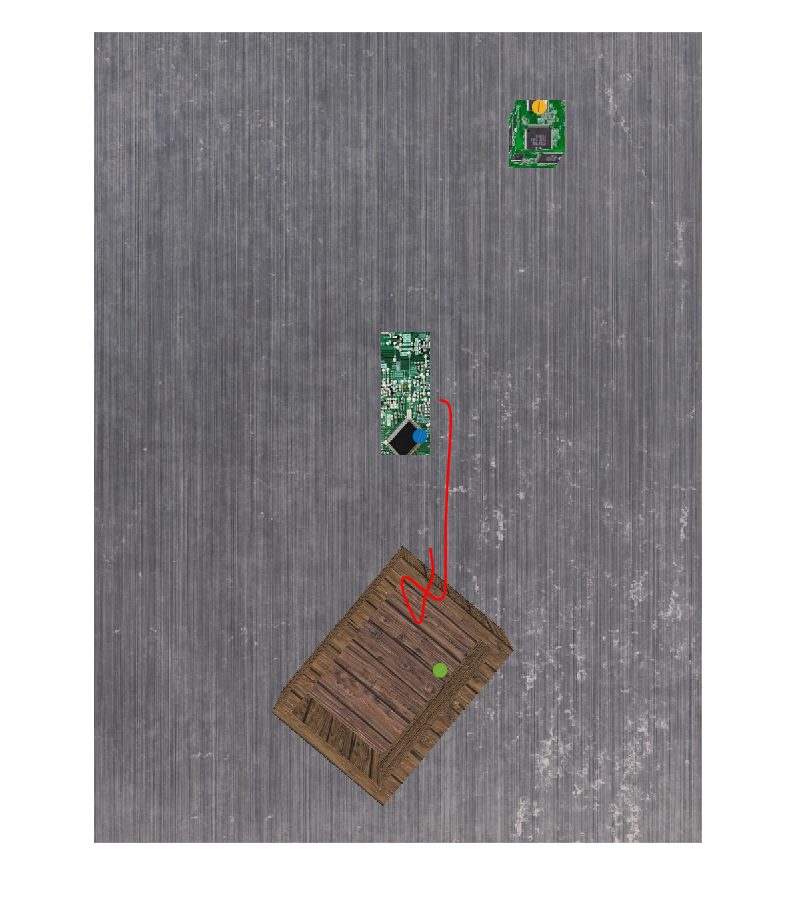

        imshow(image); hold on;

        for m=1:nbFrames_new
            tempx=-(-cntr_im(1)+(pTmp(m).b(3)-cntr_real(2)).*(widthim)./width_real);
            tempy=-(-cntr_im(2)+(pTmp(m).b(2)-cntr_real(1)).*(lengthim)./length_real);
            plot(tempx, tempy,'.','markersize',30);
            plot([tempx tempx+pTmp(m).A(2,3)], [tempy tempy+pTmp(m).A(3,3)], '-','linewidth',6);
            
            %         plot(pTmp(m).b(2), pTmp(m).b(3), '.','markersize',45,'color','yellow');
            %         plot([pTmp(m).b(2) pTmp(m).b(2)+12*pTmp(m).A(2,3)], [pTmp(m).b(3) pTmp(m).b(3)+12*pTmp(m).A(3,3)], 'MarkerSize',30,'color','black');
            
        end
        tempx=-(-cntr_im(1)+(r(1).Data(2,:)-cntr_real(2)).*(widthim)./width_real);
        tempy=-(-cntr_im(2)+(r(1).Data(1,:)-cntr_real(1)).*(lengthim)./length_real);
        plot(tempx, tempy,'-','linewidth',1.5,'color','red');
        %     plot(r(1).Data(1,:),r(1).Data(2,:), 'color','white','linewidth',2.0);
        
        %     plot(current_b(1),current_b(2), '.','markersize',35,'color','green')
        
        % do task
        returnval=vrep.simxSetIntegerSignal(id,'gripperclose',0,vrep.simx_opmode_oneshot_wait);
        for ind=1:size(MuGMR,2)
            [returnval] =vrep.simxSetObjectPosition(id, target, -1, r(1).Data(1:3,ind),...
                vrep.simx_opmode_oneshot_wait);
            
            %gripper
            if size(r(1).Data,1)>3
                if r(1).Data(4,ind)>0.5
                    returnval=vrep.simxSetIntegerSignal(id,'gripperclose',1,vrep.simx_opmode_oneshot_wait);
                else
                    returnval=vrep.simxSetIntegerSignal(id,'gripperclose',0,vrep.simx_opmode_oneshot_wait);
                end
            end
        end
        %default
        returnval=vrep.simxSetIntegerSignal(id,'gripperclose',0,vrep.simx_opmode_oneshot_wait);
        returnCode=vrep.simxSetObjectPosition(id,target,-1, target_init_pos,...
            vrep.simx_opmode_oneshot_wait);
        
%         saveas(gcf,strcat(task_path, '\results\img2_', int2str(testiter), '.jpg'));
    end
end
